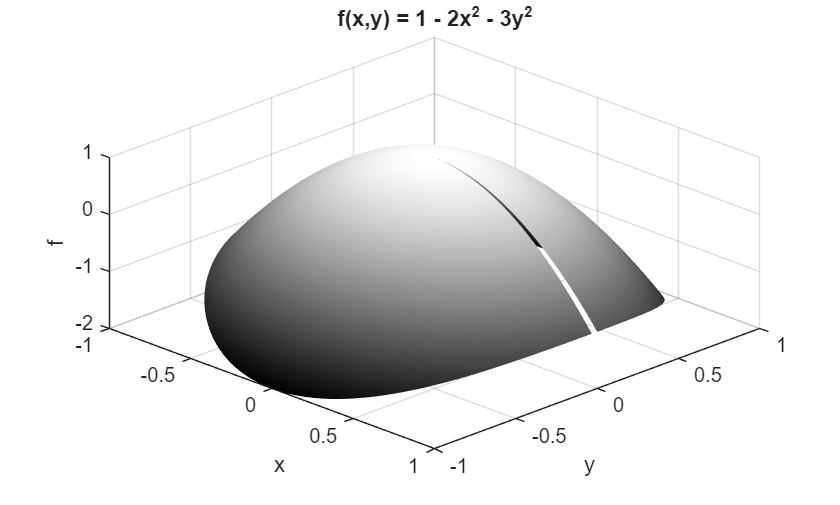

% 10.05
% Justina Korsun
% EEF-25/1

% a)
clear
close all

% f(x, y) = 1 - 2*x^2 - 3*y^2
r = 0:0.02:1;
theta = 0:0.05:2*pi;
[R, T] = meshgrid(r, theta);
x = R.*cos(T);
y = R.*sin(T);
z = 1 - 2*x.^2 - 3*y.^2;

figure
surf(x, y, z)
colormap(gray)
shading interp
view(45, 45)
title('f(x,y) = 1 - 2x^2 - 3y^2')
xlabel('x')
ylabel('y')
zlabel('f')
grid on

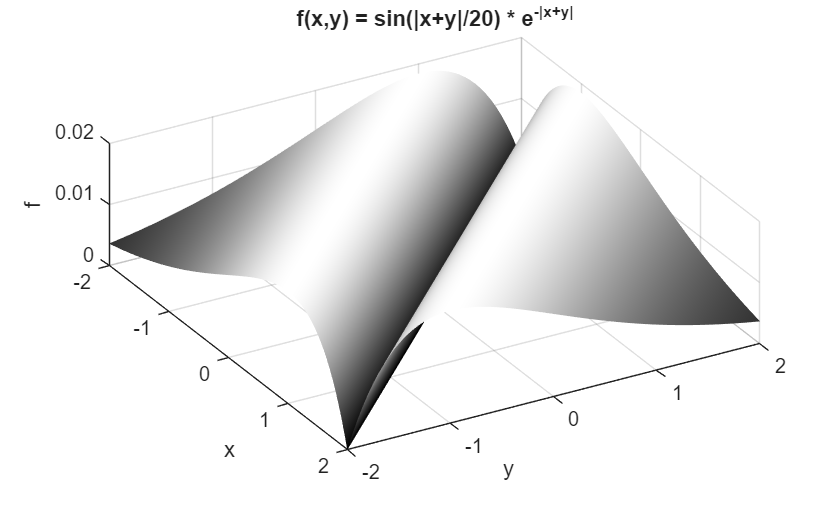

% b)
clear
close all

% f(x, y) = = sin(abs(x+y)/20) .* exp(-abs(x+y))
[x, y] = meshgrid(-2:0.05:2);
z = sin(abs(x+y)/20) .* exp(-abs(x+y));

figure
surf(x, y, z)
colormap(gray)
shading interp
view(60, 60)
title('f(x,y) = sin(|x+y|/20) * e^{-|x+y|}')
xlabel('x')
ylabel('y')
zlabel('f')
grid on

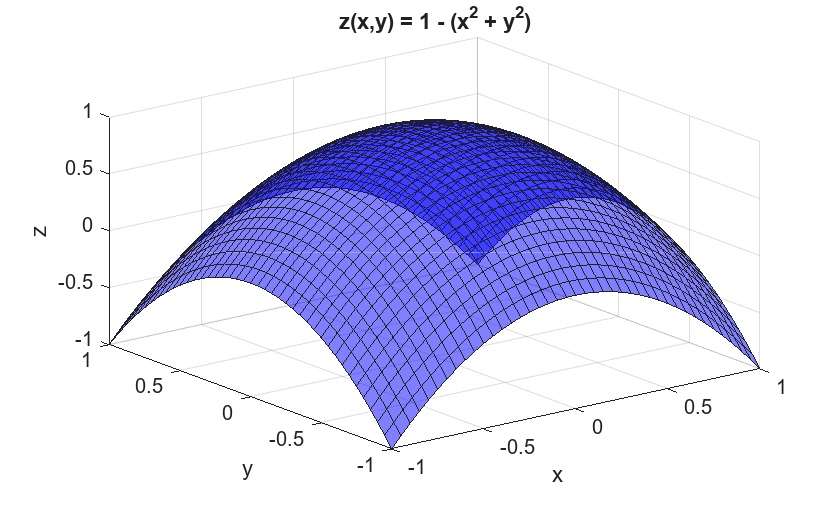

% papildoma
clear
close all

[x, y] = meshgrid(-1:0.05:1);
z = 1 - (x.^2 + y.^2);

figure
surf(x, y, z, 'FaceColor', 'b')
alpha(0.5)
title('z(x,y) = 1 - (x^2 + y^2)')
xlabel('x')
ylabel('y')
zlabel('z')
grid on